%%%%%%%%%%%%%%%%%%%%%%
%%%figure that shows Diel cycles of AROMA 
%%%created:11/3/22
%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

ppbSDKPicarro = readtimetable("ppb SDK.xlsx", "Sheet", ...
    "Picarro", "VariableNamingRule", "preserve"); %picarro data

cd ..

%SDK AROMA
ppbSDKAROMA = readtimetable("etoAROMA_SDK.xlsx");

%Houston AROMA
ppbHouAROMA = readtimetable("etoAROMA_houston.xlsx"); 

%%import met data
cd ../Met
rawMetSDK = readtimetable("Met_SDK.xlsx"); %SDK data 8/19-8/22
rawMetHou = readtimetable("Met_houston.xlsx"); %Houston 9/22
cd ../../

%%%%%%%%%%%%%%%%%%%%%%
%%% subset Picarro data to August
%%%%%%%%%%%%%%%%%%%%%%

%% Picarroa and AROMA are different time periods of data, so need to justify CRDS comparisons
%% having only August 2021 with a similar humidity diel cycle would show this
inds = isbetween(ppbSDKPicarro.time, datetime(2021, 8, 1), ...
    datetime(2021, 8, 31, 23, 59, 59));
ppbSDKPicarro = ppbSDKPicarro(inds, :);

%%%%%%%%%%%%%%%%%%%%%%
%%%bin by TOD
%%%%%%%%%%%%%%%%%%%%%%

%%use SDK Picarro as reference
numPts = 1; %minimum number of points per bin
numStd = 3; %numbers 3 standard deviations away will be removed
TTsEtO = {ppbSDKPicarro, ppbSDKAROMA(:, 2), ppbHouAROMA(:, 2)}; %ppb eto
TTsHumid = {rawMetSDK(:, end), rawMetSDK(:, end), rawMetHou(:, end)}; %humidities
timeLims = {[ppbSDKPicarro.Properties.RowTimes(1), ppbSDKPicarro.Properties.RowTimes(end)], ...
    [ppbSDKAROMA.Properties.RowTimes(1), ppbSDKAROMA.Properties.RowTimes(end)], ...
    [ppbHouAROMA.Properties.RowTimes(1), ppbHouAROMA.Properties.RowTimes(end)]};
structStr = {'SDKPicarro', 'SDKAROMA', 'HouAROMA'};

%%preallocate structure, eto
toPlotEtO = struct;
for i = 1:length(TTsEtO) %ppb eto
    TT = TTsEtO{i}; %current timetable

    %%convert time to fractional days
    times = TT.Properties.RowTimes;
    times = day(times, "dayofyear") + hour(times)/24 + minute(times)/24/60;

    data = timetable2array(TT); %grab eto data

    %%use BinAvgTOD to calculate bins
    [outMean, outStd, outN, outX] = BinAvgTOD(times, data, ...
        1, numPts, numStd, 0, 0);
    %assemble table to put into structure
    Tout = table(outX, outMean, outStd, outN);

    toPlotEtO.(structStr{i}) = Tout; %put into structure
end

%%preallocate structure, humidity
toPlotHumid = struct;
for i = 1:length(TTsHumid) %humidity
    TT = TTsHumid{i}; %current timetable
    times = TT.Properties.RowTimes;
    inds = isbetween(times, timeLims{i}(1), timeLims{i}(2)); %find matching period
    times = times(inds);
    TT = TT(inds, :);
    
    %%convert time to fractional days
    times = day(times, "dayofyear") + hour(times)/24 + minute(times)/24/60;

    data = timetable2array(TT); %grab eto data

    %%use BinAvgTOD to calculate bins
    [outMean, outStd, outN, outX] = BinAvgTOD(times, data, ...
        1, numPts, numStd, 0, 0);
    %assemble table to put into structure
    Tout = table(outX, outMean, outStd, outN);

    toPlotHumid.(structStr{i}) = Tout; %put into structure
end

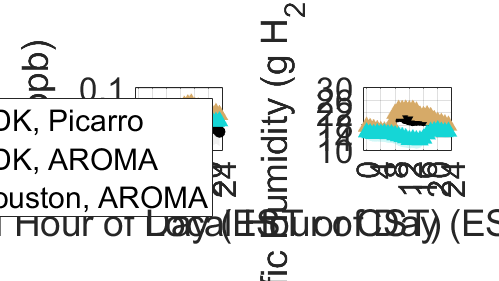

%%%%%%%%%%%%%%%%%%%%%%
%%%plot
%%%%%%%%%%%%%%%%%%%%%%

%%define colors
colors = [0, 0, 0; %picarro
    0.8392, 0.6686, 0.4098; %SDK AROMA
    0.081, 0.84, 0.84]; %Houston AROMA

%%define line types
lineTypes = {'-o', '-^', '-.^'};
markerSizes = [5, 5.5, 5.5];
transparencies = [0.06, 0.2, 0.2];

%%%plot
fig = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 2, "TileSpacing", "compact")

%%1. EtO
ax = nexttile;
hold on
grid on
box on
pbaspect([1.4, 1, 1])

hl = gobjects(length(TTsEtO), 1);

for i = 1:length(TTsEtO)
    toPlotCurrent = toPlotEtO.(structStr{i}); %current line to plot

    %%plot line
    [hl(i), ~] = boundedline(toPlotCurrent.outX, toPlotCurrent.outMean, ...
        toPlotCurrent.outStd, ...
        lineTypes{i}, ...
        'nan', 'gap', 'alpha', 'transparency', transparencies(i), ...
        'color', colors(i, :));
    hl(i).MarkerSize = markerSizes(i); %change line aspects
    hl(i).MarkerFaceColor = colors(i, :);
    hl(i).LineWidth = 4;
end

%%lims and ticks
xlim([-1, 24])
ylim([-0.0414, 0.1014])
xticks(0:4:24)

%%labels
ax.FontSize = 25;
xlabel("Local Hour of Day (EST or CST)")
ylabel("EtO (ppb)")
legend(hl(:), "SDK, Picarro", "SDK, AROMA", "Houston, AROMA", ...
    "location", "northeast")

hold off


%%2. Humidity
ax = nexttile;
hold on
grid on
box on
pbaspect([1.4, 1, 1])

hl = gobjects(length(TTsHumid), 1);

for i = 1:length(TTsHumid)
    toPlotCurrent = toPlotHumid.(structStr{i}); %current line to plot

    %%plot line
    [hl(i), ~] = boundedline(toPlotCurrent.outX, toPlotCurrent.outMean, ...
        toPlotCurrent.outStd, ...
        lineTypes{i}, ...
        'nan', 'gap', 'alpha', 'transparency', transparencies(i), ...
        'color', colors(i, :));
    hl(i).MarkerSize = markerSizes(i); %change line aspects
    hl(i).MarkerFaceColor = colors(i, :);
    hl(i).LineWidth = 4;
end

%%lims and ticks
xlim([-1, 24])
ylim([9.8, 30.2])
xticks(0:4:24)
yticks(10:4:30)

%%labels
ax.FontSize = 25;
xlabel("Local Hour of Day (EST or CST)")
ylabel("Specific Humidity (g H_2O/kg air)", "Interpreter", "tex")

hold off


% %%export the figure
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Sup diel cycles.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again
% cd ..\Data

%%%%%%%%%%%%%%%%%%%%%%
%%% calculations for paper
%%%%%%%%%%%%%%%%%%%%%%

% Outliers more than 3 standard deviations away are removed (from figure)
% n=?
% Houston AROMA
nUsed = sum(toPlotEtO.HouAROMA.outN)

nUsed = 214

nonNan = sum(~isnan(ppbHouAROMA.EtO))

nonNan = 214

nonNan - nUsed

ans = 0